# **Esercitazione 3 - EMG**

8 prove in 4 condizioni diverse.

Condizione 1 (prove 1 e 2): i soggetti dovevano compiere movimenti piccoli e lenti.

Condizione 2 (prove 3 e 4): movimenti piccoli e veloci.

Condizione 3 (prove 5 e 6): movimenti grandi e lenti.

Condizione 4 (prove 7 e 8): movimenti grandi e veloci.

load("emg_data.mat")

*Obiettivo 1: Estrarre l’inviluppo del segnale EMG per ogni soggetto per ogni prova. *

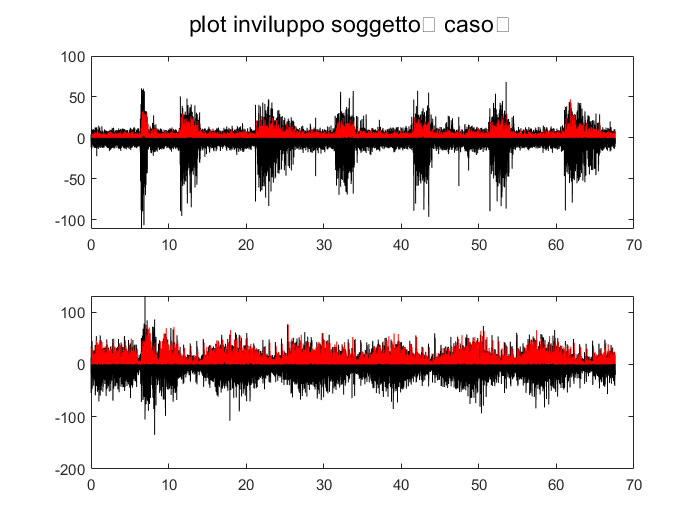

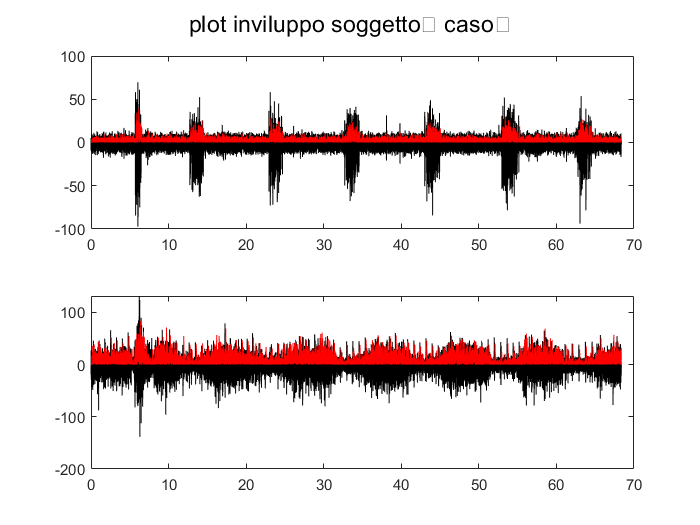

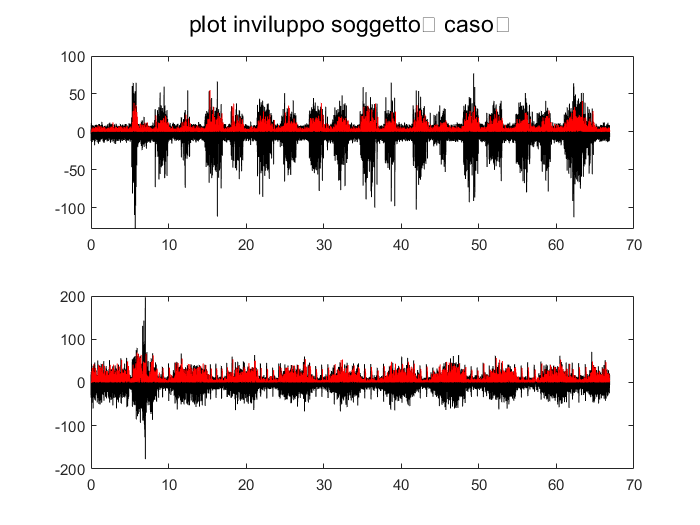

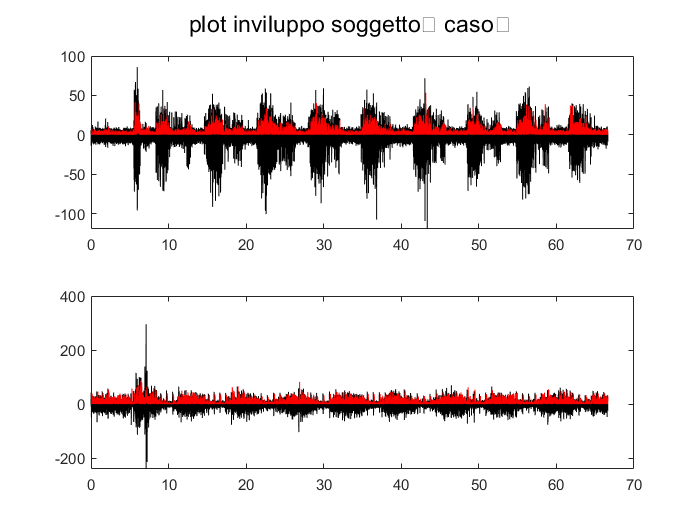

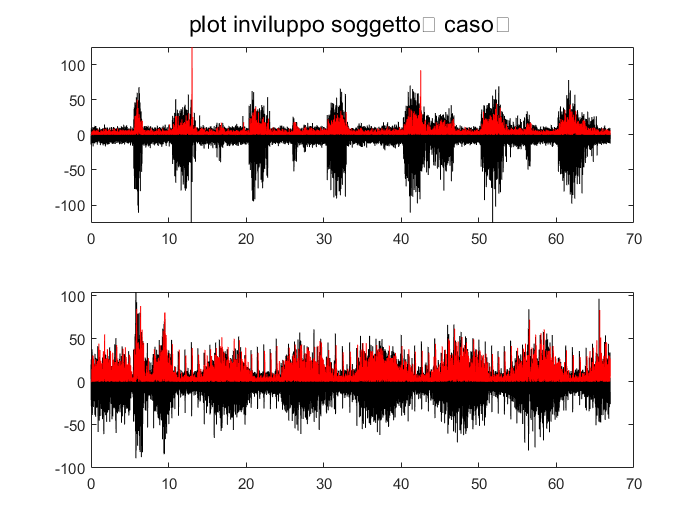

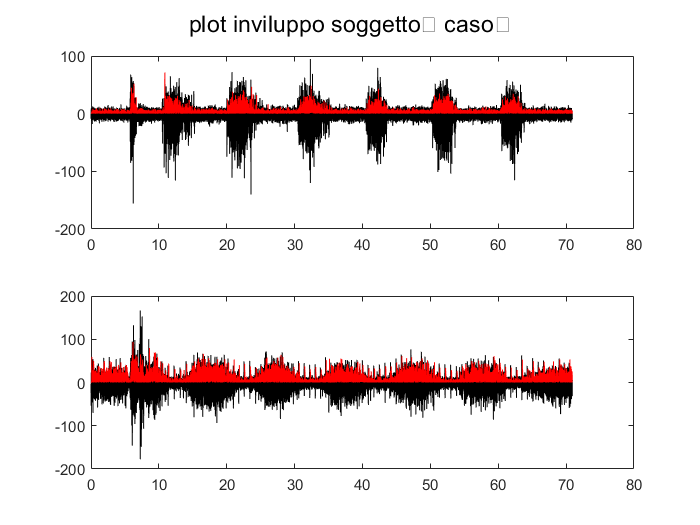

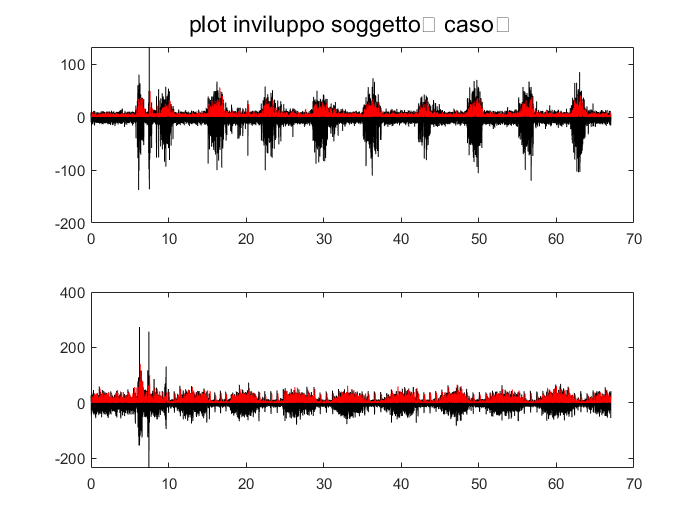

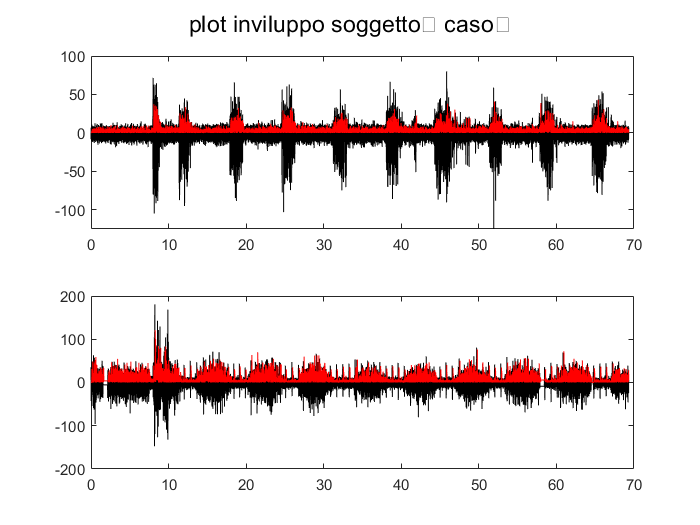

%uso della funzione get_envelope() 

fs = 2000;
nfft= 2048;

inviluppo = get_envelope (emg_data, fs, nfft);

% %uso della funzione envelope
% env= envelope (signal(:,2));
% 
% figure
% plot(signal(:,1), env)
% hold on
% plot(signal(:,1), inviluppo,"Color", "r")


*Obiettivo 2: Normalizzazione del segnale EMG rispetto al massimo valore di ogni soggetto. *

%uso funzione data_normalization()
norm=data_normalization(inviluppo); 

*Obiettivo 3: Calcolare lo spettro medio per ogni soggetto per ogni muscolo.*

overlap=100;
window=200;
[mean1, mean2] = psd( emg_data(:,1), overlap, window, nfft, 1000);

figure
semilogy(f, meanpsd_m11 ,  'Color' , 'r', 'LineWidth', 2) 

Unrecognized function or variable 'meanpsd_m11'.

hold on 
semilogy(f, meanpsd_m12 ,  'Color' , 'b', 'LineWidth', 2) 

*Obiettivo 4: Trovare le attivazioni per ogni soggetto e per ogni prova.*

%uso funzione detect_activation()

%activation sample1  multiplier=0.5
%cell to save the activation
activation_muscle1=cell([8 1]); 
activation_muscle2=cell([8 1]); 
for index=1:8
   [peaks1,time_peaks1]=detect_activation(cell2mat(sample1_muscle1_norm(index,1)),cell2mat(sample1_time(index,1)),0.5);    
   [peaks2,time_peaks2]=detect_activation(cell2mat(sample1_muscle2_norm(index,1)),cell2mat(sample1_time(index,1)),0.5);
   %salvo in ogni entrata una matrice con prima colonna i tempi dei picchi e seconda colonna i valori dei picchi 
   activation_muscle1{index,1}=[time_peaks1;peaks1];
   activation_muscle2{index,1}=[time_peaks2;peaks2];
end
my_plot(activation_muscle1,activation_muscle2);

%activation sample2  multiplier=0.1
%cell to save the activation
activation2_muscle1=cell([8 1]); 
activation2_muscle2=cell([8 1]); 
for index=1:8
   [peaks1,time_peaks1]=detect_activation(cell2mat(sample2_muscle1_norm(index,1)),cell2mat(sample2_time(index,1)),0.1);  %muscle1
   [peaks2,time_peaks2]=detect_activation(cell2mat(sample2_muscle2_norm(index,1)),cell2mat(sample2_time(index,1)),0.1);  %muscle2
   %salvo in ogni entrata una matrice con prima colonna i tempi dei picchi e seconda colonna i valori dei picchi 
   activation2_muscle1{index,1}=[time_peaks1;peaks1];
   activation2_muscle2{index,1}=[time_peaks2;peaks2];
end
my_plot(activation2_muscle1,activation2_muscle2);

%activation sample3  multiplier=0.2
%cell to save the activation
activation3_muscle1=cell([8 1]); 
activation3_muscle2=cell([8 1]); 
for index=1:8
   [peaks1,time_peaks1]=detect_activation(cell2mat(sample3_muscle1_norm(index,1)),cell2mat(sample3_time(index,1)),0.2);  %muscle1
   [peaks2,time_peaks2]=detect_activation(cell2mat(sample3_muscle2_norm(index,1)),cell2mat(sample3_time(index,1)),0.2);  %muscle2
   %salvo in ogni entrata una matrice con prima colonna i tempi dei picchi e seconda colonna i valori dei picchi 
   activation3_muscle1{index,1}=[time_peaks1;peaks1];
   activation3_muscle2{index,1}=[time_peaks2;peaks2];
end
my_plot(activation3_muscle1,activation3_muscle2);

*Obiettivo 5: Visualizzazione delle singole attivazioni nelle 4 condizioni.*

...

*Obiettivo 6: calcolare e visualizzare la durata di attivazione media per ogni soggetto e per ogni prova.*

uso full_width at half maximum

...

*Obiettivo 7: Effettuare un permutation test sui dati tramite l'utilizzo di una funzione.*

%uso funzione my_permutation_test()